Trying out PCA explicitly with intermediate steps as well as using the high level function in MATLAB "pca"

addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))

%Operations
ops0.fig                       = 1;
ops0.saveData                  = 1;
ops0.loadSyntheticData         = 1;

% Load Dataset
make_db
if ops0.loadSyntheticData
    setupSyntheticDataParameters
end

% Save details
saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


i = length(sdcp);
if ops0.loadSyntheticData
        load([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' num2str(sdcp(i).eventAmplificationFactor) ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end
trialDetails = getTrialDetails(db);

Getting trial details ...
... done!



nCells = size(myData.dfbf_2D, 1);
nFrames = size(myData.dfbf_2D, 2);

%Remember to transpose the 2D data to rows - allFrames (observations), and columns - Cells (variables)
X = (myData.dfbf_2D)';

## DIRECT LOGIC

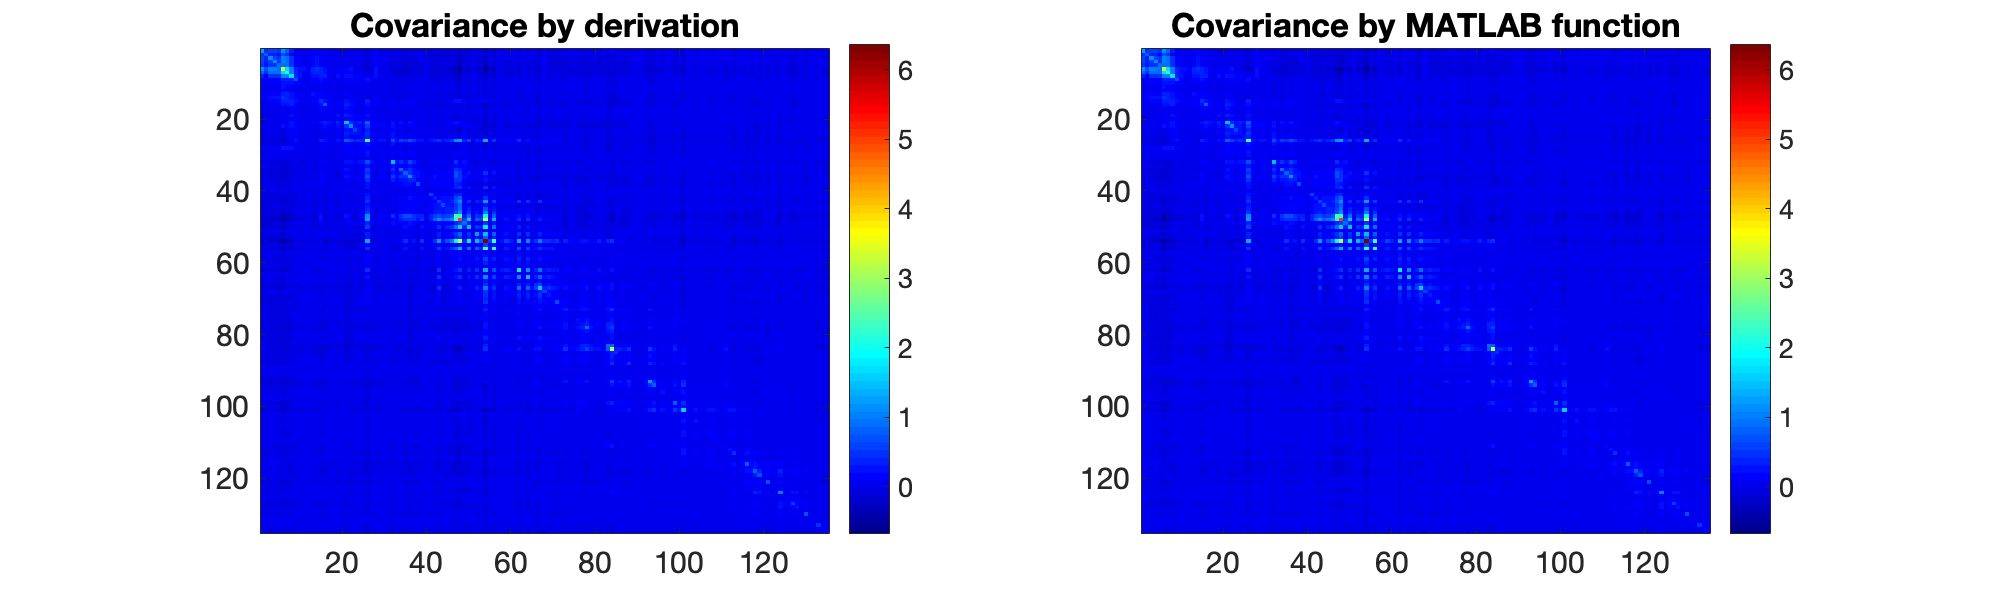

%Develop the centered and standardized matrix from the 2D Data.
for i = 1:nCells
    Z(:, i) = X(:, i) - mean(X(:, i)); %Subtract column mean
    %Z(:, i) = Z(:, i) / std(X(:, i)); %Divide by column standard deviation
end

%Covariance matrix - by derivation
Cd = (Z' * Z) / (size(Z, 1) - 1);

C = cov(X); %Using a Matlab function directly

if ops0.fig
    fig1 = figure(1);
    set(fig1,'Position',[300,300,1000,300])
    subplot(1,2,1)
    imagesc(Cd)
    colorbar
    colormap('jet')
    title('Covariance by derivation', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
    
    subplot(1,2,2)
    imagesc(C)
    colorbar
    colormap('jet')
    title('Covariance by MATLAB function', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
end

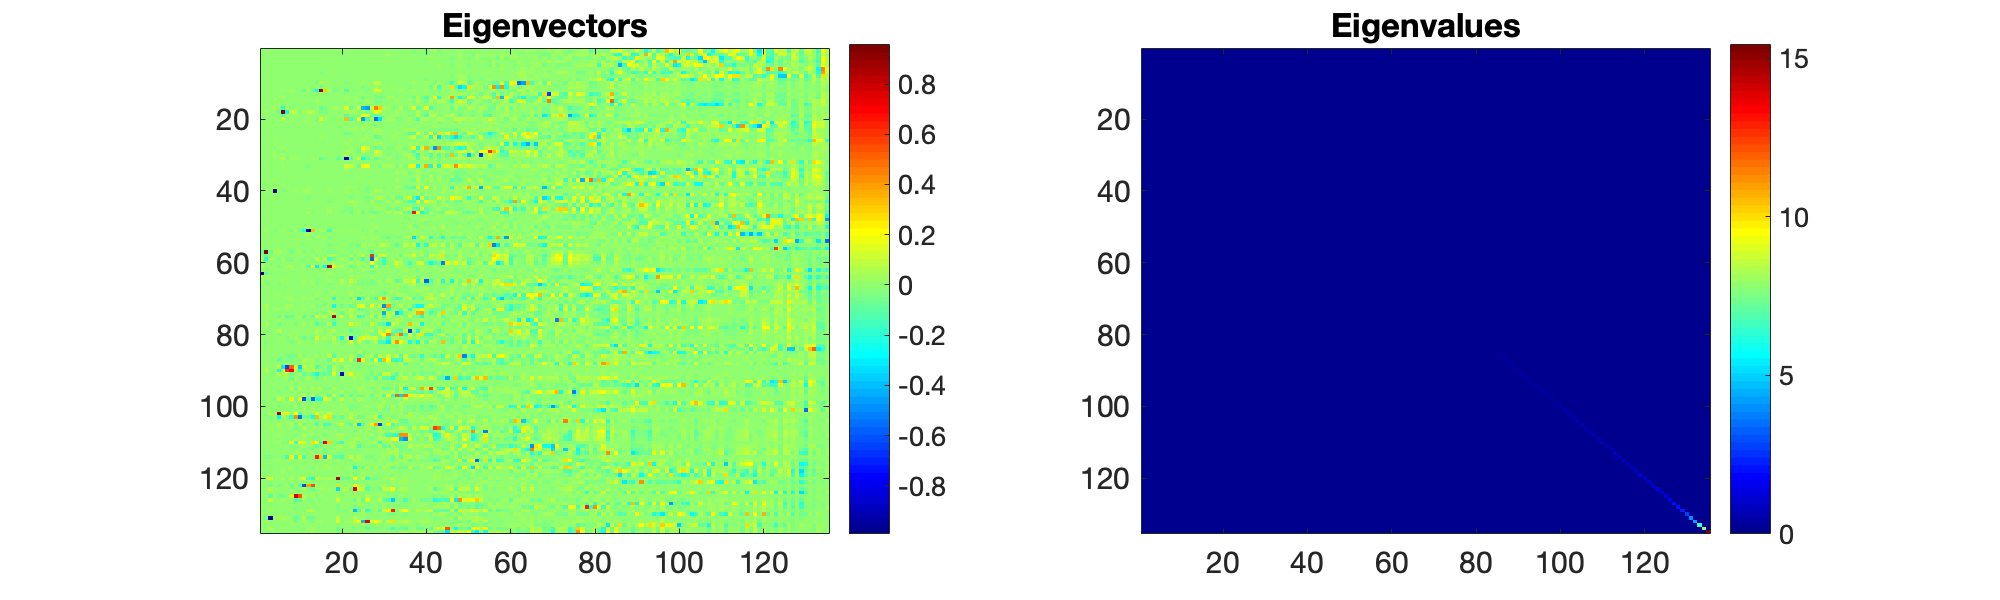

%Get the eigenvectors and eigenvalues
[V, D] = eig(C); % V = coeff; D = latent
if ops0.fig
    fig2 = figure(2);
    set(fig2,'Position',[300,300,1000,300])
    subplot(1,2,1)
    imagesc(V)
    colorbar
    colormap('jet')
    title('Eigenvectors', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
    
    subplot(1,2,2)
    imagesc(D)
    colorbar
    colormap('jet')
    title('Eigenvalues', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
end

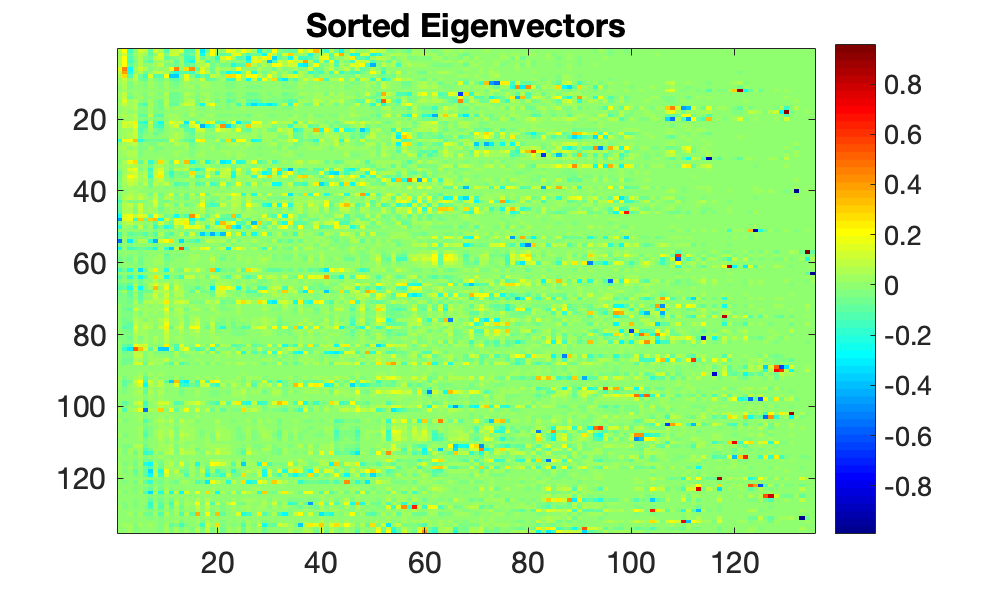

%Sort columns of the eigenvector matrix after sorting the eigenvalues
[sortedD, indices] = sort(diag(D), 'descend');
sortedV = V(:, indices);
if ops0.fig
    fig3 = figure(3);
    set(fig3, 'Position', [300, 300, 500, 300])
    imagesc(sortedV)
    colorbar
    colormap('jet')
    title('Sorted Eigenvectors', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
end

% Develop a Centered/Standardized version of the 2D dF/F matrix (cells, allFrames)
Zstar = Z * sortedV;

nPCDs = 3;
V1 = sortedV(1, 1); %Only the first PC
Zstar1 = Z * V1;
%residuals1 = pcares(X, nPCDs);

V2 = sortedV(1:50, 1:50); 
Zstar2 = Z * V2;

Error using  * 
Inner matrix dimensions must agree.

%residuals2 = pcares(X, 1);

if ops0.fig
    fig4 = figure(4);
    set(fig4, 'Position', [300, 300, 1000, 800])
    subplot(2, 2, 1)
    imagesc(myData.dfbf_2D)
    colorbar
    colormap('jet')
    title('Actual Data', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 2)
    imagesc(Zstar')
    colorbar
    colormap('jet')
    title('Recreated using PCA', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)

    subplot(2, 2, 3)
    imagesc(Zstar1')
    colorbar
    colormap('jet')
    title('Recreated using PCA - Only 1st PC', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 4)
    imagesc(Zstar2')
    colorbar
    colormap('jet')
    title('Recreated using PCA - First 50 PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    set(gca, 'FontSize', 15)
    
end

## USING HIGH-LEVEL FUNCTIONS

%[coeff, score, latent, tsquared, explained, mu] = pca(X, 'NumComponents', 5);
[coeff, score, latent, tsquared, explained, mu] = pca(X);

if ops0.fig
    fig5 = figure(5);
    set(fig5, 'Position', [300, 300, 1000, 500])
    subplot(2, 2, 1)
    imagesc(score)
    colorbar
    colormap('jet')
    title('Representation of X in PC Space', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 2)
    imagesc(coeff)
    colorbar
    colormap('jet')
    title('Eigenvectors', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 3)
    plot(latent)
    title('Scree Plot', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Eigenvalues', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 4)
    plot(explained)
    title('Scree Plot', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Total Variance Explained (%)', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
end
if ops0.fig
    fig6 = figure(6);
    set(fig6, 'Position', [300, 300, 1000, 500])
    subplot(2, 2, 1)
    imagesc(((score * coeff') + mu)')
    colorbar
    colormap('jet')
    title('Data - All PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 2)
    imagesc(((score(:,1) * coeff(:, 1)') + mu)')
    colorbar
    colormap('jet')
    title('Data - Only 1st PC', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 3)
    imagesc(((score(:,1:3) * coeff(:, 1:3)') + mu)')
    colorbar
    colormap('jet')
    title('Data - First 3 PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 4)
    imagesc(((score(:,1:50) * coeff(:, 1:50)') + mu)')
    colorbar
    colormap('jet')
    title('Data - First 50 PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
end
